# 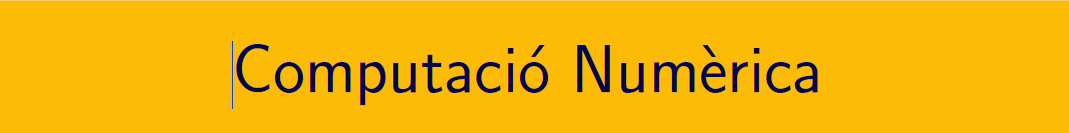

================================================================================

# Pràctica 12. Equacions diferencials ordinàries.

`Document preparat per M. Àngela Grau Gotés - 17 de maig de 2021`

# Mètodes d'aproximació numèrica

## **PVI  **$y^{\prime}(t)=y(t)+t^2\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

### DSOLVE: Solució analítica 

syms y(t)
eqn = diff(y,t) == t^2+y;
cond = y(0) == 1;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 3\,{\mathrm{e}}^{t}-2\,t-t^{2}-2$$

La solució es pot respresentar a l'interval [0,1]

% fplot(ySol,[0,1])

#### Isoclines del camp de direccions y'=f(t,y)

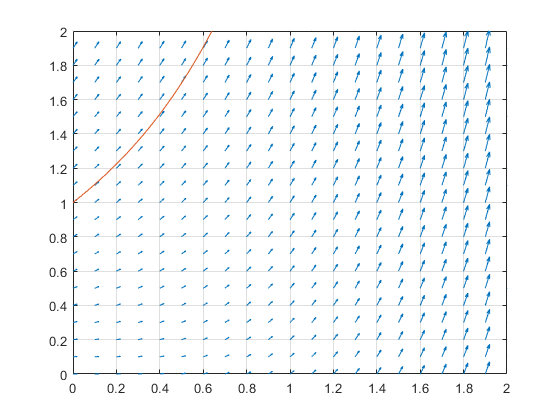

t = 0:0.1:2; 
y = 0:0.1:2;
[TT,YY] = meshgrid(t,y);
DT = ones(size(TT));
f = @(t,y)(t.^2+y);
DY = f(TT,YY);
% Gràfic
figure(1)
quiver(TT,YY,DT,DY);grid,axis([0,2,0,2]), hold on
fplot(ySol,[0,1]), hold off

### Solucions aproximades numèricament

#### `Mètode d'Euler per h = 0.2, h = 0.1 ....`

% Yn+1 = Yn + h * f(tn,Yn)
a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(t^2+y);
h = 0.2;
x = a:h:b; 
[Y1] = Euler(f,a,b,h,alpha);
errorlocal = abs(Y1-double(ySol(x)))

errorlocal =             0     0.024208     0.067474      0.13676       0.2411      0.39222


errorGlobal = abs(Y1(end)-double(ySol(b)))

errorGlobal =       0.39222


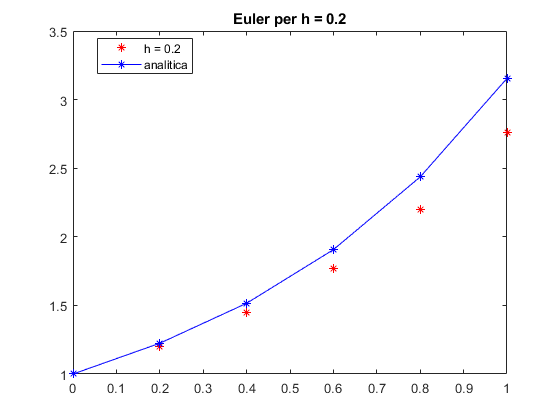

plot(x,Y1,'*r',x,ySol(x),'b-*'), title(['Euler per h = ', num2str(h)]), legend('h = 0.2','analitica','Location','best')

#### `Mètode d'Euler modificat`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
[YM1] = EulerMod( f,a,b,h,alpha );
errorlocal = abs(YM1-double(ySol(x)))

errorlocal =             0    0.0022083    0.0058341     0.011396     0.019571     0.031242


errorGlobal = abs(YM1(end)-double(ySol(b)))

errorGlobal =      0.031242


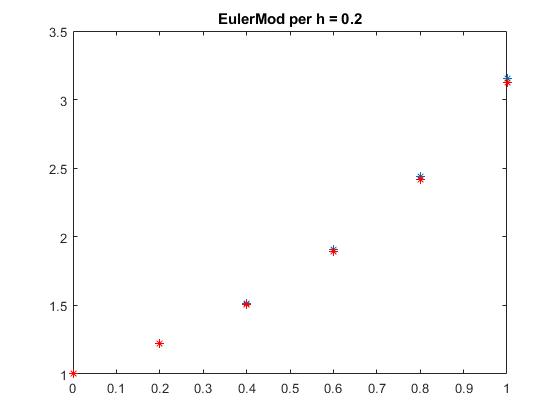

plot(x,ySol(x),'*',x,YM1,'*r'), title(['EulerMod per h = ', num2str(h)])

#### `Mètode de Heun`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...

[YH1] = Heun(f,a,b,h,alpha);
errorlocal = abs(YH1-double(ySol(x)))

errorlocal =             0   0.00020827    0.0013941    0.0039788    0.0085221     0.015763


errorGlobal = abs(YH1(end)-double(ySol(b)))

errorGlobal =      0.015763


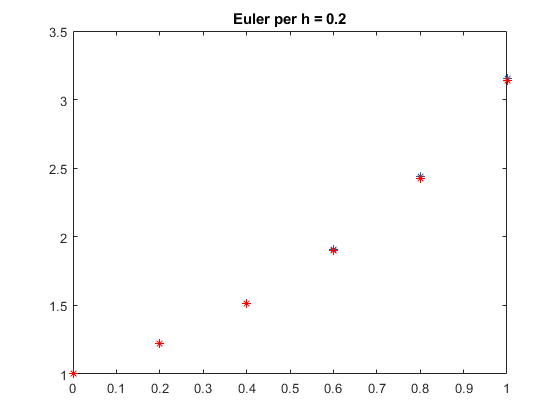

plot(x,ySol(x),'*',x,YH1,'*r'), title(['Euler per h = ', num2str(h)])

#### `Mètode RK4`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...

[ YK1 ] = RK4( f,a,b,h,alpha );
errorlocal = abs(YK1-double(ySol(x)))

errorlocal =             0   1.6078e-06   5.4036e-06   1.2277e-05   2.3406e-05   4.0337e-05


errorGlobal = abs(YK1(end)-double(ySol(b)))

errorGlobal =    4.0337e-05


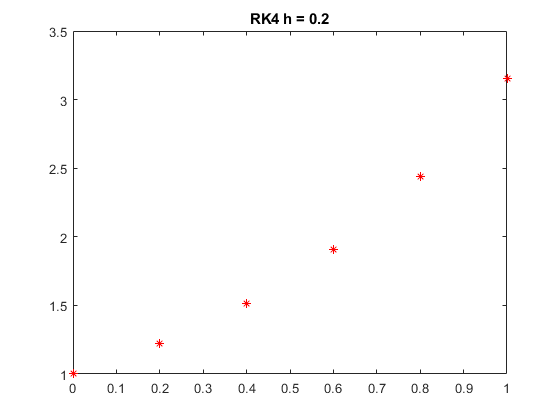

plot(x,ySol(x),'*',x,YK1,'*r'), title(['RK4 h = ', num2str(h)])

% Es compara amb càlculs de f, Heun h = 0.1, RK4 = h = 0.2.

#### `Solvers de MATLAB: ode23, ode45`

tspan = [0 1];
y0 = 1;        
ode = @(t,y)(t^2+y);
[t1,y1] = ode23(ode, tspan, y0);
disp([t1,y1])

            0            1
         0.08       1.0835
         0.18       1.1992
         0.28        1.331
         0.38       1.4824
         0.48       1.6578
         0.58       1.8617
         0.68       2.0992
         0.78       2.3759
         0.88       2.6982
         0.98       3.0728
            1       3.1547



errorGlobal = abs(y1(end)-double(ySol(1)))

errorGlobal =    0.00016887


[t2,y2] = ode45(ode, tspan, y0);
disp([t2,y2])

            0            1
        0.025       1.0253
         0.05       1.0513
        0.075        1.078
          0.1       1.1055
        0.125       1.1338
         0.15        1.163
        0.175       1.1931
          0.2       1.2242
        0.225       1.2563
         0.25       1.2896
        0.275        1.324
          0.3       1.3596
        0.325       1.3965
         0.35       1.4347
        0.375       1.4743
          0.4       1.5155
        0.425       1.5581
         0.45       1.6024
        0.475       1.6484
          0.5       1.6962
        0.525       1.7458
         0.55       1.7973
        0.575       1.8508
          0.6       1.9064
        0.625       1.9641
         0.65       2.0241
        0.675       2.0865
          0.7       2.1513
        0.725       2.2186
         0.75       2.2885
        0.775       2.3612
          0.8       2.4366
        0.825        2.515
         0.85       2.5964
        0.875        2.681
          0.9       2.7688
 

errorGlobal = abs(y2(end)-double(ySol(1)))

errorGlobal =    1.0482e-08


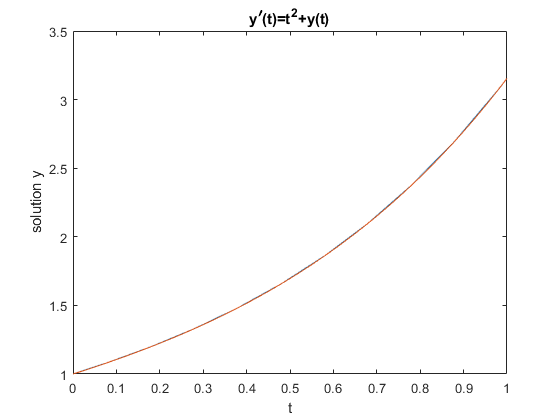

% Plot solution
plot(t1,y1,t2,y2)
xlabel('t')
ylabel('solution y')
title('y^{\prime}(t)=t^2+y(t)')